# **SISTEMAS DE CONTROL DISCRETO                                **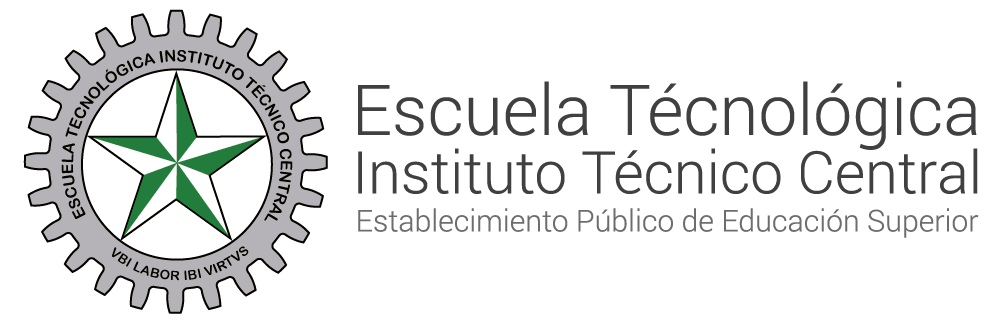

# **Lugar Geometrico de las Raícez **

#### Autor ING. JHEYSON FABIAN VILLAVISAN BUITRAGO MS.c

#### Coautor: HEISSY BRIGITTE CASTRO HURTADO

#### OBJETIVO

Al finalizar esta sesión, los estudiantes serán capaces de entender y aplicar el concepto de lugar geométrico de las raíces en el análisis de sistemas de control. Identificarán cómo varían las raíces de un polinomio característico al modificar los parámetros del sistema y cómo esto impacta la estabilidad y la dinámica del sistema. Además, desarrollarán habilidades para utilizar herramientas analíticas y computacionales para trazar y analizar estos lugares geométricos, facilitando así el diseño y ajuste de controladores.

**LGR**

El Lugar Geométrico de las Raíces (LGR) es una técnica esencial en el análisis y diseño de sistemas de control. Esta **herramienta gráfica **proporciona una visión clara de cómo las raíces de la ecuación característica de un sistema, es decir, los polos del sistema se desplazan en el plano complejo en respuesta a variaciones en los parámetros del sistema. Entender cómo se comportan estas raíces es fundamental porque determinan directamente la estabilidad y el comportamiento dinámico del sistema.

## VALOR MARGINAL DE K PARA ESTABILIDAD

Siendo $k$ el parametro variable o ganancia, es quien cambia o modifica la respuesta sistema de control al cual se aplica. Teniendo limites 

Cuando se tiene la ecuacion caracteristica del sistema de control en tiempo discreto, es necesario realizar el analisis desde el paso 1 para encontrar los LGR, en este caso el paso 1 se debe realizar de forma inverza, con el fin de llevar la ecuacion caracteristica a la funcion de transferencia inicial. 

#### Paso 1 de forma inverza

Obtener la funcion de transferencia apartir de la ecuación característica 


$$1+ F(z)=0$$


en donde $F\left(z\right)$ esta representado por la función de transferencia $\frac{k*N\left(z\right)}{D\left(z\right)}$ 


$$1+\frac{k*N\left(z\right)}{D\left(z\right)}=0$$


se remplaza 1 para hacer un denominador comun para ambos terminos.


$$\frac{D\left(z\right)}{D\left(z\right)}+\frac{\textrm{kN}\left(z\right)}{D\left(z\right)}=0$$
 
$$\longrightarrow$$
 
$$\frac{D\left(z\right)+\textrm{kN}\left(z\right)}{D\left(z\right)}=0$$


pasa el denominador a multiplicar despues del igual.


$$D\left(z\right)+\textrm{kN}\left(z\right)=0*D\left(z\right)$$


quedando la siguiente expresion 


$$D\left(z\right)+\textrm{kN}\left(z\right)=0$$


como se evidencia esta expresion se asemeja a la ecuacion caracteristica, determinado asi la funcion de transferencia donde los elementos que hacen parte del numerador son los que incluyen k, mientras los que no incluyen k son parte del denominador.


$$\textrm{FT}=\frac{\textrm{kN}\left(z\right)}{D\left(z\right)}$$


#### Ejemplo

Dada la siguiente ecuacion caracteristica del sistema de control en tiempo discreto, contruya el LGR pra K>0. Determine el valor marginal de K para estabilidad. 


$${\mathit{\mathbf{z}}}^3 +{\textrm{kz}}^2 +1,5\textrm{kz}-\left(\mathit{\mathbf{k}}+1\right)=0$$


Primero se relizan los procedimientos algebraicos correspondientes:


$${\mathit{\mathbf{z}}}^3 +{\textrm{kz}}^2 +1,5\textrm{kz}-k-1=0$$


Pasar la ecuancion carcateristica a la forma $\textrm{FT}=\frac{\textrm{kN}\left(z\right)}{D\left(z\right)}$; teniendo en cuenta que los terminos del nuemerador son los que incluyen k


$${\mathit{\mathbf{z}}}^3 +{\textrm{kz}}^2 +1,5\textrm{kz}-\mathit{\mathbf{k}}-1=0\;\;\;\;\longrightarrow \;\;\;\textrm{FT}=\frac{{\textrm{kz}}^2 +1,5\textrm{kz}-k}{{\mathit{\mathbf{z}}}^3 -1}\;\;\;\;$$


Se factoriza la k en el nuerando obteniendo finalmente la siguiente funcion de transferencia. 


$$\textrm{FT}=\frac{k\left({\mathit{\mathbf{z}}}^2 +1,5\mathit{\mathbf{z}}-1\right)}{{\mathit{\mathbf{z}}}^3 -1}$$


Comprobando por medio de codigo obtenemos 

clear all
clc
numerador = [1 1.5 -1];          % Numerador del sistema
d_0 = [1 -1];                   % Primera parte del denominador
d_1 = [1 1 1];               % Segunda parte del denominador
denominador = conv(d_0, d_1);   % Convolución de los denominadores
ts = 1;                         % Tiempo de muestreo
fprintf('*** Función de Transferencia Discreta ***\n');

*** Función de Transferencia Discreta ***


sistema = tf(numerador, denominador, ts)

sistema =
 
  z^2 + 1.5 z - 1
  ---------------
      z^3 - 1
 
Sample time: 1 seconds
Discrete-time transfer function.



teniendo la *FT, *se procede al paso 2.

#### Paso 2

Encontrar y dibujar los puntos de inicio y final. Ceros y Polos

De la siguiente forma se hallan los Ceros del sistema


$$\frac{{\mathit{\mathbf{z}}}^2 +1,5\mathit{\mathbf{z}}-1}{{\mathit{\mathbf{z}}}^3 -1}$$


de la funcion se toman los terminos del numerador, en este caso se factoriza este trinomio de la siguiente forma.


$${\mathit{\mathbf{z}}}^2 +1,5\mathit{\mathbf{z}}-1$$



$$\left(z+2\right)\left(z-0,5\right)$$



$$z=-2$$



$$z=0,5$$


cantidad de ceros =2

fprintf('*** Calcular ceros del sistema ***\n');

*** Calcular ceros del sistema ***


ceros = zero(sistema)

ceros =    -2.0000
    0.5000


De la siguiente forma se hallan los Polos del sistema


$$\frac{{\mathit{\mathbf{z}}}^2 +1,5\mathit{\mathbf{z}}-1}{{\mathit{\mathbf{z}}}^3 -1}$$


de la funcion se toman los terminos del denominador.


$${\mathit{\mathbf{z}}}^3 -1=0$$


Dando solucion a la ecuacion encontrada se obtiene.


$$\left(z-1\right)\left(z^2 +z+1\right)=0$$


Aplicando la ecuación cuadrática de la forma $z=\frac{-b\pm \sqrt{b^2 -4\textrm{ab}}}{2a}$ se obtiene:


$$z=\frac{-1\pm \sqrt{1^2 -4\left(1\right)\left(1\right)}}{2\left(1\right)}$$



$$z=\frac{-1\pm \sqrt{1-4\;}}{2}\;\;\;\longrightarrow \;\;\;z=\frac{-1\pm \sqrt{-3}}{2}\;\;\;\;$$



$$z=\frac{-1+1\ldotp 73i}{2}$$
      
$$z=\frac{-1-1\ldotp 73i}{2}$$


$z_2 =-0,5+0,866i$ y $z_3 =-0,5-0,866i$ 


$$z-1=0$$



$$\textrm{z1}=1$$


cantidad de polos =3

Comprobando por medio de codigo obtenemos 

% Graficar el Lugar Geométrico de las Raíces (LGR)
fprintf('*** Calcular polos del sistema ***\n');

*** Calcular polos del sistema ***


polos = pole(sistema)

polos =   -0.5000 + 0.8660i
  -0.5000 - 0.8660i
   1.0000 + 0.0000i


fprintf('*** Graficar el Lugar Geométrico de las Raíces (LGR) ***\n');

*** Graficar el Lugar Geométrico de las Raíces (LGR) ***


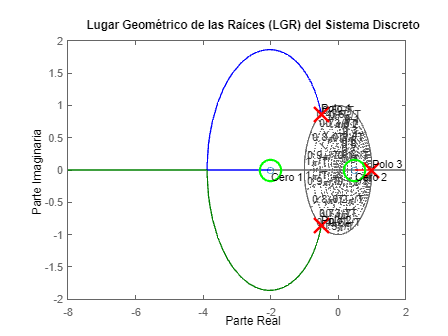

figure;
rlocus(sistema);
title('Lugar Geométrico de las Raíces (LGR) del Sistema Discreto');
xlabel('Parte Real');
ylabel('Parte Imaginaria');
grid on;

hold on;
plot(real(polos), imag(polos), 'rx', 'MarkerSize', 20, 'LineWidth', 2); % Polos (x en rojo)
plot(real(ceros), imag(ceros), 'go', 'MarkerSize', 20, 'LineWidth', 2); % Ceros (o en verde)

for k = 1:length(polos)
    text(real(polos(k)), imag(polos(k)), sprintf('Polo %d', k), 'VerticalAlignment', 'bottom');
end
for k = 1:length(ceros)
    text(real(ceros(k)), imag(ceros(k)), sprintf('Cero %d', k), 'VerticalAlignment', 'top');
end


fprintf('polos del sistema\n');

polos del sistema


n_polos = length(polos)

n_polos = 3

fprintf('Ceros del sistema\n');

Ceros del sistema


n_ceros = length(ceros)

n_ceros = 2

#### Paso 3

A continuación se procede a encontrar las asintotas y sus angulos:

para en contrar las asintotas se usa la siguiente formula. 


$$\frac{180\left(2N+1\right)}{n-m}=0$$



$$\begin{array}{l}
N=k\;;\;k=0\\
n=\textrm{numero}\;\textrm{de}\;\textrm{polos}\\
m=\textrm{numero}\;\textrm{de}\;\textrm{ceros}
\end{array}$$


remplazamos los valores del sistema


$$\frac{180\left(2\left(0\right)+1\right)}{3-2}=0$$



$$\frac{180}{1}=180$$


Comprobando por medio de codigo obtenemos 

%%
n_asintotas = n_polos - n_ceros

n_asintotas = 1

angulo_asintotas = 0

centro_asintotas = 1.5000

*** Ángulos de las asíntotas ***


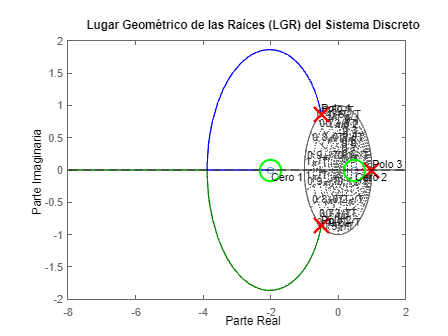

if n_asintotas > 0
    suma_polos = sum(real(polos));
    suma_ceros = sum(real(ceros));
    angulo_asintotas = (0:n_asintotas-1) * (180 / n_asintotas)   
    centro_asintotas = (suma_polos - suma_ceros) / n_asintotas
    fprintf('*** Ángulos de las asíntotas ***\n');
    % Graficar cada asíntota
    for k = 1:n_asintotas
        theta = angulo_asintotas(k) * pi / 180; % Convertir a radianes
        x_asintota = real(centro_asintotas) + [-100, 100] * cos(theta);
        y_asintota = imag(centro_asintotas) + [-100, 100] * sin(theta);
        plot(x_asintota, y_asintota, '--k', 'LineWidth', 1); % Asíntota en línea negra discontinua
    end
end

Las asintotas se representan en la grafica por medio de una linea punteda, sobre el eje real (*eje x*)

#### Paso 4

Se procede hallando la intersección de las asintotas, usando la siguiente formula:


$$\sigma =\frac{\Sigma \textrm{polos}-\Sigma \textrm{ceros}}{n-m}$$


Reemplazando los valores dle sistema se obtiene


$$\sigma =\frac{\left(1+\left(-0,5+0,866i\right)+\left(-0,5-0,866i\right)\right)-\left(-2+0,5\right)}{3-2}$$



$$\sigma =\frac{\left(1+\left(-1\right)\right)-\left(-1,5\right)}{3-2}$$



$$\sigma =\frac{0-\left(-1,5\right)}{1}$$



$$\sigma =\frac{1\ldotp 5}{1}\;\;\;\;\;\longrightarrow \sigma =1,5$$


if n_asintotas > 0
suma_polos = sum(real(polos));
suma_ceros = sum(real(ceros));
fprintf('Punto de intersección de las asíntotas\n');
centro_asintotas = (suma_polos - suma_ceros) / n_asintotas
end

Punto de intersección de las asíntotas


centro_asintotas = 1.5000

#### Paso 5

El siguiente paso es encontrar el punto de rutura, utilizando la ecuacion:


$$1+kG\left(z\right)=0\;\;;\;\;\;\;\;\;G\left(z\right)=\frac{{\mathit{\mathbf{z}}}^2 +1,5\mathit{\mathbf{z}}-1}{{\mathit{\mathbf{z}}}^3 -1}$$
     


$$kG\left(z\right)=-1\;\;\;\longrightarrow \;\;\;\;k=-\frac{1}{G\left(z\right)}$$



$$k=-\frac{1}{G\left(z\right)}\;\;\;\longrightarrow \;\;\;\;k=-\frac{1}{\frac{{\mathit{\mathbf{z}}}^2 +1,5\mathit{\mathbf{z}}-1}{{\mathit{\mathbf{z}}}^3 -1}}$$



$$k=-\frac{{\mathit{\mathbf{z}}}^3 -1}{{\mathit{\mathbf{z}}}^2 +1,5\mathit{\mathbf{z}}-1}$$


Para necontrar los puntos de ruptura es necesario derivar la ecuacion anterior asi:


$$\frac{\textrm{dk}}{\textrm{dz}}=\frac{d\;}{\textrm{dz}}\left(\frac{-\left({\mathit{\mathbf{z}}}^3 -1\right)}{{\mathit{\mathbf{z}}}^2 +1,5\mathit{\mathbf{z}}-1}\right)$$



$$\;\;\;\;\;-\frac{d\;}{\textrm{dz}}\left(\frac{{\mathit{\mathbf{z}}}^3 -1}{{\mathit{\mathbf{z}}}^2 +1,5\mathit{\mathbf{z}}-1}\right)$$


Para derivar la ecuacion anterior se aplica la regla de cocientes para derivadas

 
$${\left(\frac{\mathit{\mathbf{f}}}{g}\right)}^{\prime } =\frac{{\mathit{\mathbf{f}}}^{\prime } *g-g^{\prime } *f}{g^2 }$$



$${\left(\frac{{\mathit{\mathbf{z}}}^3 -1}{{\mathit{\mathbf{z}}}^2 +1,5\mathit{\mathbf{z}}-1}\right)}^{\prime } =-\left(\frac{\left({\left({\mathit{\mathbf{z}}}^3 -1\right)}^{\prime } *\left({\mathit{\mathbf{z}}}^2 +1,5\mathit{\mathbf{z}}-1\right)\right)-\left(\left({\mathit{\mathbf{z}}}^3 -1\right)*{\left({\mathit{\mathbf{z}}}^2 +1,5\mathit{\mathbf{z}}-1\right)}^{\prime } \right)}{{\left({\mathit{\mathbf{z}}}^2 +1,5\mathit{\mathbf{z}}-1\right)}^2 }\right)$$



$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=-\left(\frac{\left({3\mathit{\mathbf{z}}}^2 *\left({\mathit{\mathbf{z}}}^2 +1,5\mathit{\mathbf{z}}-1\right)\right)-\left(\left({\mathit{\mathbf{z}}}^3 -1\right)*2z+1\ldotp 5\right)}{{\left({\mathit{\mathbf{z}}}^2 +1,5\mathit{\mathbf{z}}-1\right)}^2 }\right)$$



$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=-\left(\frac{\left(3{\mathit{\mathbf{z}}}^4 +4,5z^3 -{3\mathit{\mathbf{z}}}^2 \right)-\left({2\mathit{\mathbf{z}}}^4 +{1\ldotp 5\mathit{\mathbf{z}}}^3 -2z-1\ldotp 5\right)}{{\left({\mathit{\mathbf{z}}}^2 +1,5\mathit{\mathbf{z}}-1\right)}^2 }\right)$$



$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=-\left(\frac{3{\mathit{\mathbf{z}}}^4 +4,5z^3 -{3\mathit{\mathbf{z}}}^2 -{2\mathit{\mathbf{z}}}^4 -{1\ldotp 5\mathit{\mathbf{z}}}^3 +2z+1\ldotp 5}{{\left({\mathit{\mathbf{z}}}^2 +1,5\mathit{\mathbf{z}}-1\right)}^2 }\right)$$



$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=-\left(\frac{{\mathit{\mathbf{z}}}^4 +3z^3 -{3\mathit{\mathbf{z}}}^2 +2z+1\ldotp 5}{{\left({\mathit{\mathbf{z}}}^2 +1,5\mathit{\mathbf{z}}-1\right)}^2 }\right)$$



$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;0=-\frac{{\mathit{\mathbf{z}}}^4 +3z^3 -{3\mathit{\mathbf{z}}}^2 +2z+1\ldotp 5}{{\left({\mathit{\mathbf{z}}}^2 +1,5\mathit{\mathbf{z}}-1\right)}^2 }$$


 
$${\left({\mathit{\mathbf{z}}}^2 +1,5\mathit{\mathbf{z}}-1\right)}^2 *0=-\left({\mathit{\mathbf{z}}}^4 +3z^3 -{3\mathit{\mathbf{z}}}^2 +2z+1\ldotp 5\right)$$



$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;0=-{\mathit{\mathbf{z}}}^4 -3z^3 +{3\mathit{\mathbf{z}}}^2 -2z-1\ldotp 5$$


Para resolver este polinomio y encontrar los puntos de ruptura se usa el siguiente codigo 

Polinomio=[-1, -3, 3, -2, -1.5];
disp('puntos de ruptura:');

puntos de ruptura:


disp(roots(Polinomio));

  -3.8803 + 0.0000i
   0.6449 + 0.7267i
   0.6449 - 0.7267i
  -0.4095 + 0.0000i



#### Paso 6

#### Criterio de JURY - Condiciones de estabilidad

Finalmente para este paso se usa la funcion de transferencia, tomando el denominador de esta primero se identifican las condiciones de estabilidad y despues se aplica el criterio de JURY; si el sistema no cumple con las condiciones significa que no el mismo es inestable, las condiciones a evaluar son las siguientes:


$$\frac{k\left({\mathit{\mathbf{z}}}^2 +1,5\mathit{\mathbf{z}}-1\right)}{{\mathit{\mathbf{z}}}^3 -1}$$



$$P\left(z\right)={\mathit{\mathbf{z}}}^3 -1$$


## Condiciones: 

## $*\;\left|a_0 \right|<a_n$ esta condicion indica que, deacuerdo con el polinomio a evaluar el ultimo termino debe ser menor al primero, en este caso el pirmer termino ${\mathit{\mathbf{z}}}^3$ que acompaña la z y el ultimo es $-1$, dando como respuesta que primera condicion se cumple.

                    
$${\mathit{\mathbf{z}}}^3 -1=$$

$$\overbrace{{\mathit{\mathbf{z}}}^3 } +0+0\overbrace{-1} \;\;\;\;\;\;\;\;\longrightarrow \;\;\;\;\;\left|a_0 \right|<a_n =-1<1$$
         

## $*\;P\left(z\right)|z_{=1} >0,$ para esta condicion se requiere remplazar en el polinomio las z por el valor de 1, y el resultado de las opraciones algebraicas debe ser mayor que cero. Para esta condicion el polinomio no cumple puesto que el valor resultante debe ser mayor que 0 

                    
$$\begin{array}{l}
{\mathit{\mathbf{z}}}^3 -1={\left(1\right)}^3 -1\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\longrightarrow \;\;\;\;\;\;\;\;=1-1\;\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=0\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;
\end{array}$$


## * $\begin{array}{l}
P\left(z\right)|z_{=-1} >0\;\textrm{para}\;n\;\textrm{par}\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;<0\;\textrm{para}\;n\;\textrm{impar}
\end{array}$,   esta condicion indica que se requiere remplazar en el polinomio las z por el valor -1, y el resultado de las operaciones algebraicas tiene dos posibilidades de acuerdo al grado (*n) *del polinomio. Si el polinomio es de grado par el valor debe ser mayor que 0; si el polinomio el de grado impar el valor resultante debe ser menor que 0. En el caso de este polinomio que es de grado impar, el resultado debera ser menor que 0, esta condicion si la cumple. 

                      
$$\begin{array}{l}
{\mathit{\mathbf{z}}}^3 -1={\left(-1\right)}^3 -1\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\longrightarrow \;\;\;\;\;\;\;\;=-1-1\;\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=-2\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;
\end{array}$$


Teniendo en cuenta que una de las condiciones no cumple, se puede determinar que el sistema es inestable. Esto se puede evidenciar en la grafica del LGR, donde al aumentar el valor de k las raices se alejan de la region de convergencia.     

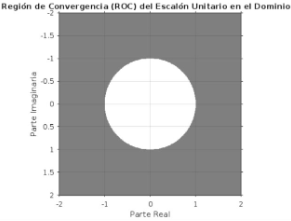 

La grafica muesta que los polos del sistema se encuentar en el limite de la region de convergencia y que mientras aumente el valor k las raices se alejan mucho mas de la region convergente. Dando a entender que al variar la ganancia (k) en el controlador, la respuesta del mismo sera instable.

% estabilidad del sistema
numerador = [1, 1.5, -1];   % Numerador del sistema
denominador = [1, 0, 0, -1];   % Denominador del sistema

% Definir el tiempo de muestreo
ts = 1; % Tiempo de muestreo

% Crear el sistema de transferencia discreto

sistema = tf(numerador, denominador, ts)

sistema =
 
  z^2 + 1.5 z - 1
  ---------------
      z^3 - 1
 
Sample time: 1 seconds
Discrete-time transfer function.




% Definir el rango de ganancias k para el análisis
k = (0:0.01:24);  % Rango de valores de ganancia

% Graficar el Lugar Geométrico de las Raíces (LGR)
fprintf('* Representacion de estabilidad *\n');

* Representacion de estabilidad *


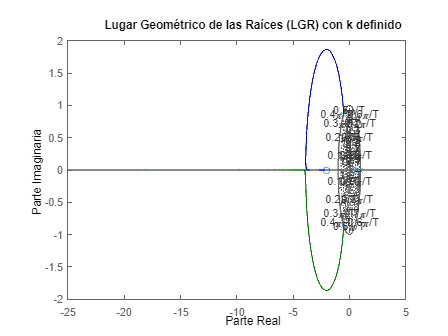

figure;
rlocus(sistema,k);
title('Lugar Geométrico de las Raíces (LGR) con k definido');
xlabel('Parte Real');
ylabel('Parte Imaginaria');
grid on;

## Ahora en caso de que el sistema fuera estable. se aplica el criterio de JURY.

#### Criterio de JURY

El criterio de JURY es un metodo para encontrar los valores marginales de k, asi mismo identificar el rango de ganancia que puede tener el sistema sin perder la estabilidad. 

Para realizar el criterio de JURY, se toma la ecuacion caracteristica entregad desde el inicio, y se organizan en una fila los terminos que acompañan la z (en orden de z)  menor a mayor; en una fila inferior a esta se organiza de nuevo los terminos que acompañan la z (en orden de z) pero de mayor a menor, de la siguiente forma:


$${\mathit{\mathbf{z}}}^3 +{\textrm{kz}}^2 +1,5\textrm{kz}-\left(\mathit{\mathbf{k}}+1\right)=0$$
 


$$-\left(\mathit{\mathbf{k}}+1\right)\;\;\;\;\;\;\;1,5k\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;k\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;1\;\;\;\;\;$$


       
$$1\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;k\;\;\;\;\;\;\;\;\;\;\;\;\;1,5k\;\;\;\;\;\;\;-\left(\mathit{\mathbf{k}}+1\right)$$


Despues de organizar los terminos, el siguiente paso es hacer la tabla de JURY; la tabla se forma encontrando los valores de las determinantes entre los dos terminos ubicados en la primera columna, inicialmente por los dos terminos de la ultima columna y luego por los terminos de la siguiente columna. En este caso se obtendra para comenzar 2 terminios b1, b2 y b3.


$$\textrm{b1}=\left\lbrace \begin{array}{ll}
-\left(\mathit{\mathbf{k}}+1\right) & \;\;\;\;\;\;\;\;\;\;1\\
\;\;\;\;\;\;\;\;\;\;1 & -\left(\mathit{\mathbf{k}}+1\right)
\end{array}\;\;\;=\;\;\;\left(-\left(\mathit{\mathbf{k}}+1\right)*-\left(\mathit{\mathbf{k}}+1\right)\right)-\left(1*1\right)\;\;=\left(k^2 +k+k+1\right)-1\;\;={\;\;k}^2 +2k\right.$$
 


$$\textrm{b2}=\left\lbrace \begin{array}{ll}
-\left(\mathit{\mathbf{k}}+1\right) & \;\;\;\;\;k\\
\;\;\;\;\;\;\;\;\;\;1 & 1,5k
\end{array}\;\;\;=\;\;\left(-\left(\mathit{\mathbf{k}}+1\right)*1,5k\right)-\left(1*k\right)\;\;=\left(-1,5k^2 -1,5k\right)-k=\;-1,5k^2 -2,5k\;\right.$$



$$\textrm{b3}=\left\lbrace \begin{array}{ll}
-\left(\mathit{\mathbf{k}}+1\right) & \;1,5k\\
\;\;\;\;\;\;\;\;\;\;1 & \;\;\;\;k
\end{array}\;\;\;=\;\;\left(-\left(\mathit{\mathbf{k}}+1\right)*k\right)-\left(1*1,5k\right)\;\;=\left(-k^2 -k\right)-1,5k=\;-k^2 -2,5k\;\right.$$


Los resultados obtenidos b1, b2 y b3, se organizan en un nuevo polinomio de la siguiente forma:


$${\;\;k}^2 +2k-1,5k^2 -2,5k-k^2 -2,5k\;=0$$


En este caso se organizan en la tabla, la primera fila en el orden en el cual se encontraron los resultados; en la fila inferior a esta los resultados en sentido contrario del ultimo al primero; por ultimo se encuentran los determinantes hallando c1 y c2, de la siguiente forma:


$${\;\;\;\;\;k}^2 +2k\;\;\;\;\;\;\;\;\;\;\;\;-1,5k^2 -2,5k\;\;\;\;\;\;\;\;\;-k^2 -2,5k$$



$$-k^2 -2,5k\;\;\;\;\;\;\;\;\;-1,5k^2 -2,5k\;\;\;\;\;\;\;\;\;\;\;\;\;{\;\;\;k}^2 +2k\;\;$$
     


$$\begin{array}{l}
\textrm{c1}=\left\lbrace \begin{array}{ll}
{\;\;\;\;\;k}^2 +2k\; & -k^2 -2,5k\\
-k^2 -2,5k & {\;\;\;\;\;k}^2 +2k\;
\end{array}\;\;\;=\;\;\;\left(\left({\;\;\;k}^2 +2k\;\right)*\left({\;\;\;k}^2 +2k\;\right)\right)-\left(\left(-k^2 -2,5k\right)*\left(-k^2 -2,5k\right)\right)=\left({\;k}^4 +2k^3 +2k^3 +4k^2 \;\right)-\left({\;k}^4 +2,5k^3 +2,5k^3 +6,25k^2 \;\right)\right.\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;={\;\;k}^4 +4k^3 +4k^2 -k^4 -5k^3 -6,25k^2 \;\;=-{\mathit{\mathbf{k}}}^3 -2,25k^2 
\end{array}$$



$$\begin{array}{l}
\textrm{c2}=\left\lbrace \begin{array}{ll}
{\;\;\;\;\;k}^2 +2k\; & \;\;\;\;-1,5k^2 -2,5k\\
-k^2 -2,5k & \;\;\;\;-1,5k^2 -2,5k
\end{array}\;\;\;=\;\;\;\left(\left({\;\;\;k}^2 +2k\;\right)*\left(-1,5k^2 -2,5k\;\right)\right)-\left(\left(-k^2 -2,5k\right)*\left(-1,5k^2 -2,5k\right)\right)=\left({\;-1,5k}^4 -3k^3 -2,5k^3 -5k^2 \;\right)-\left(1,5{\;k}^4 +2,5k^3 +3,75k^3 +6,25k^2 \;\right)\right.\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;={\;\;-1,5\;k}^4 -5,5k^3 -5k^2 -1,5k^4 -6,25k^3 -6,25k^2 \;\;=-\;{3\mathit{\mathbf{k}}}^4 -11,75k^3 -11,25k^2 
\end{array}$$


Los resultados obtenidos c1 y c2, se organizan en un nuevo polinomio de la siguiente forma:


$${-\mathit{\mathbf{k}}}^3 -2,25k^2 -\;{3\mathit{\mathbf{k}}}^4 -11,75k^3 -11,25k^2 =0$$


En este caso se organizan en la tabla, la primera fila en el orden en el cual se encontraron los resultados; en la fila inferior a esta los resultados en sentido contrario del ultimo al primero; por ultimo se encuentran los determinantes hallando d1, de la siguiente forma:


$$\begin{array}{l}
\textrm{d1}=\left\lbrace \begin{array}{ll}
\;\;\;\;\;\;\;\;\;\;\;\;\;\;-{\mathit{\mathbf{k}}}^3 -2,25k^2  & \;\;\;-\;{3\mathit{\mathbf{k}}}^4 -11,75k^3 -11,25k^2 \\
-\;{3\mathit{\mathbf{k}}}^4 -11,75k^3 -11,25k^2  & \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;-\;{\mathit{\mathbf{k}}}^3 -2,25k^2 
\end{array}\;\;\;=\;\;\;\left(\left(-{\mathit{\mathbf{k}}}^3 -2,25k^2 \;\right)*\left(-{\mathit{\mathbf{k}}}^3 -2,25k^2 \right)\right)-\left(\left(-\;{3\mathit{\mathbf{k}}}^4 -11,75k^3 -11,25k^2 \right)*\left(-\;{3\mathit{\mathbf{k}}}^4 -11,75k^3 -11,25k^2 \right)\right)=\left({\;k}^6 +2,25k^5 +2,25k^5 +2,25k^4 \;\right)-\left(9{\;k}^8 +35,25k^7 +33,75k^6 +35,25k^7 +138,06k^6 +132,18k^5 +33,75k^6 +132,18k^5 +126,56k^4 \;\right)\right.\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\left({\;k}^6 +4,5k^5 +2,25k^4 \;\right)-\left(9{\;k}^8 +67,5k^7 +205,56k^6 +264,36k^5 +126,56k^4 \;\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;={\;k}^6 +4,5k^5 +2,25k^4 \;-9{\;k}^8 -67,5k^7 -205,56k^6 -264,36k^5 -126,56k^4 \;\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=-9{\;k}^8 -67,5k^7 -204,56k^6 -259,86k^5 -124,31k^4 \;
\end{array}$$


Para comprobar los resultados anteriores se usa el codigo acontinuacion.

%matriz jury p1
syms k % Declarar la variable simbólica

A = [-(k+1), 1.5*k, k, 1; 
     1, k, 1.5*k, -(k+1)]; % Matriz de 2 filas y 4 columnas

disp('Terminos inicales:');

Terminos inicales:


disp(A); % Mostrar la matriz

$$\left(\begin{array}{cccc} -k-1 & \frac{3\,k}{2} & k & 1\\ 1 & k & \frac{3\,k}{2} & -k-1 \end{array}\right)$$


%matriz b1
fprintf('Matriz b1 \n');

Matriz b1 


b1=[-(k+1), 1; 1, -(k+1)]

$$b1 = \left(\begin{array}{cc} -k-1 & 1\\ 1 & -k-1 \end{array}\right)$$

fprintf('Determiante b1 \n');

Determiante b1 


b1=det(b1)% Calcular el determinante

$$b1 = k^{2}+2\,k$$


%matriz b2
b2 = [-(k+1), k; 1, 1.5*k]; % Definir la matriz
disp('Matriz b2:');

Matriz b2:


disp(b2); % Mostrar la matriz

$$\left(\begin{array}{cc} -k-1 & k\\ 1 & \frac{3\,k}{2} \end{array}\right)$$

det_b2 = det(b2); % Calcular el determinante
disp('Determinante de b2:');

Determinante de b2:


disp(det_b2); % Mostrar el determinante

$$-\frac{3\,k^{2}}{2}-\frac{5\,k}{2}$$


%matriz b3
b3 = [-(k+1), 1.5*k; 1, k]; % Definir la matriz
disp('Matriz b3:');

Matriz b3:


disp(b3); % Mostrar la matriz

$$\left(\begin{array}{cc} -k-1 & \frac{3\,k}{2}\\ 1 & k \end{array}\right)$$

det_b3 = det(b3); % Calcular el determinante
disp('Determinante de b3:');

Determinante de b3:


disp(det_b3); % Mostrar el determinante

$$-k^{2}-\frac{5\,k}{2}$$


c1 = [b1, det_b3; det_b3, b1]; % Definir la matriz
disp('Matriz c1:');

Matriz c1:


disp(c1); % Mostrar la matriz

$$\left(\begin{array}{cc} k^{2}+2\,k & -k^{2}-\frac{5\,k}{2}\\ -k^{2}-\frac{5\,k}{2} & k^{2}+2\,k \end{array}\right)$$

det_c1 = det(c1); % Calcular el determinante
disp('Determinante de c1:');

Determinante de c1:


disp(det_c1); % Mostrar el determinante

$$-k^{3}-\frac{9\,k^{2}}{4}$$


c2 = [b1, det_b2 ; det_b3, det_b2]; % Definir la matriz
disp('Matriz c2:');

Matriz c2:


disp(c2); % Mostrar la matriz

$$\left(\begin{array}{cc} k^{2}+2\,k & -\frac{3\,k^{2}}{2}-\frac{5\,k}{2}\\ -k^{2}-\frac{5\,k}{2} & -\frac{3\,k^{2}}{2}-\frac{5\,k}{2} \end{array}\right)$$

det_c2 = det(c2); % Calcular el determinante
disp('Determinante de c2:');

Determinante de c2:


disp(det_c2); % Mostrar el determinante

$$-3\,k^{4}-\frac{47\,k^{3}}{4}-\frac{45\,k^{2}}{4}$$


d1 = [det_c1, det_c2; det_c2, det_c1]; % Definir la matriz
disp('Matriz d1:');

Matriz d1:


disp(d1); % Mostrar la matriz

$$\left(\begin{array}{cc} -k^{3}-\frac{9\,k^{2}}{4} & -3\,k^{4}-\frac{47\,k^{3}}{4}-\frac{45\,k^{2}}{4}\\ -3\,k^{4}-\frac{47\,k^{3}}{4}-\frac{45\,k^{2}}{4} & -k^{3}-\frac{9\,k^{2}}{4} \end{array}\right)$$

det_d1 = det(d1); % Calcular el determinante
disp('Determinante de d1:');

Determinante de d1:


disp(det_d1); % Mostrar el determinante

$$-9\,k^{8}-\frac{141\,k^{7}}{2}-\frac{3273\,k^{6}}{16}-\frac{2079\,k^{5}}{8}-\frac{243\,k^{4}}{2}$$


syms k real
% Definir las filas de la tabla
z0 = [-(k+1), 1, -(k+1), 1, -(k+1), 1, (k^2+2*k), (-k^2-5*k/2), (k^2+2*k), (-k^2-5*k/2), (-k^3-9*k^2/4), (-3*k^4-47*k^3/4-45*k^2/4)];
z1 = [0, 0, 0, 0, (1.5*k), k, 0, 0, (-3*k^2/2-5*k/2), (-3*k^2/2-5*k/2), (-3*k^4-47*k^3/4-45*k^2/4), (-k^3-9*k^2/4)];
z2 = [0, 0, k, (1.5*k), 0, 0, (-k^2-5*k/2), (k^2+2*k), 0, 0, 0, 0];
z3 = [1, -(k+1), 0, 0, 0, 0, 0, 0, 0, 0, 0, 0];
Resultados = [0, (k^2+2*k), 0, (-3*k^2/2-5*k/2), 0, (-k^2-5*k/2), 0, (-k^3-9*k^2/4), 0, (-3*k^4-47*k^3/4-45*k^2/4), 0, -9*k^8-141*k^7/2-3273*k^6/16-2079*k^5/8-243*k^4/2];

% Convertir todos los valores a decimales
z0_decimal = vpa(z0);
z1_decimal = vpa(z1);
z2_decimal = vpa(z2);
z3_decimal = vpa(z3);
Resultados_decimal = vpa(Resultados);

% Crear la tabla
tabla = table(z0_decimal', z1_decimal', z2_decimal', z3_decimal', Resultados_decimal', ...
    'VariableNames', {'z0', 'z1', 'z2', 'z3', 'Resultados'});

disp(tabla);

                   z0                                   z1                           z2                 z3                              Resultados                    
    _________________________________    _________________________________    _________________    _____________    __________________________________________________

    - 1.0*k - 1.0                        0                                    0                    1.0              0                                                 
    1.0                                  0                                    0                    - 1.0*k - 1.0    k^2 + 2.0*k                                       
    - 1.0*k - 1.0                        0                                    k                    0                0                                            

#### Respuesta del ejemplo

Para terminar el resulado que se requierie inicialmente, el cual es los valores marginales de k, para la estabilidad del sistema es **incierto**, al encontrar que el mismo es un sistema inestable inicalmente. Para modificar esta inestabilidad es necerario aplicar un elemento al sistema que corriga la instabilidad .

k=38

k = 38

numerador = [k*1 1.5 -1];
denominador = [1, 0, 0, -1];
Ts = 1; 
sys = tf(numerador, denominador,Ts)/(1+tf(numerador, denominador,Ts))

sys =
 
      38 z^5 + 1.5 z^4 - z^3 - 38 z^2 - 1.5 z + 1
  ---------------------------------------------------
  z^6 + 38 z^5 + 1.5 z^4 - 3 z^3 - 38 z^2 - 1.5 z + 2
 
Sample time: 1 seconds
Discrete-time transfer function.



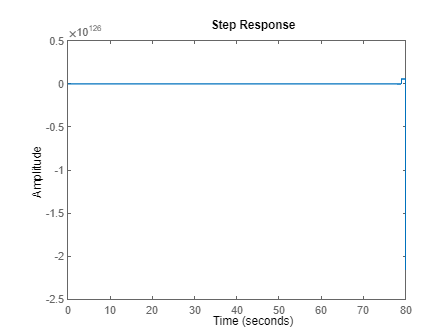


step(sys);